**Equações de montagem dos modelos ligado e desligado do MOSFET:**

    Cmed: Matriz de espaço de estado que seleciona a saída desejada na matriz de variaveis de estado, no nosso caso a polaridade é invertida em função da troca do comportamento do indutor, então optamos por -1 na seleção da variável.

syms R L C D V0 IL s Vin
%EQUACOES MONTAGEM DO MODELO MÈDIO:---------------------------------------------
I = eye(2);

Aon  = [(-1/(R*C)) 0 ; 0 0];
Aoff = [(-1/(R*C)) (1/C);(-1/L)  0];


Bon= [0 ; 1/L];
Boff=[0;0];


Cmed = [-1 0];
Dmat = 0;

**Montagem do modelo médio das equações de espaço de estado:**

    Pelo sistema possuri dois estados, a linearização destes estados levando em conta o duty cicle fixo e os componentes ativos com comportamento ideal pode ser descrito como a construção do modelo médio de duração de cada uma das fases dessa dinâmica, para o MOSFET ligado (D) e para o mesfet desligado (1-D).

Amed = (Aon*D) + (Aoff*(1-D));
Amed = simplify(Amed)

$$Amed = \left(\begin{array}{cc} -\frac{1}{C\,R} & -\frac{\text{D}-1}{C}\\ \frac{\text{D}-1}{L} & 0 \end{array}\right)$$


Bmed= (Bon*D) + (Boff*(1-D))

$$Bmed = \left(\begin{array}{c} 0\\ \frac{\text{D}}{L} \end{array}\right)$$

**Substituição das varíáveis no espaço de estado para obtenção dos resultados:**

    Neste bloco realizo a montagem do espaço de estados completo, em seguido aplico uma entrada degral*24 referente ao nosso Vin para confirmação.

Amed_num = Amed;
Amed_num = subs(Amed_num,[R, L, C, D], [4 , 20e-6 , 80e-6 , 0.4]);

Bmed_num = Bmed;
Bmed_num = subs(Bmed_num,[R, L, C, D], [4 , 20e-6 , 80e-6 , 0.4]);

Amed_num=double(Amed_num)

Amed_num =        -3125        7500
      -30000           0


Bmed_num=double(Bmed_num)

Bmed_num =            0
       20000



espaco_de_estado = ss(Amed_num , Bmed_num , Cmed , Dmat)

espaco_de_estado =
 
  A = 
           x1      x2
   x1   -3125    7500
   x2  -3e+04       0
 
  B = 
          u1
   x1      0
   x2  2e+04
 
  C = 
       x1  x2
   y1  -1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



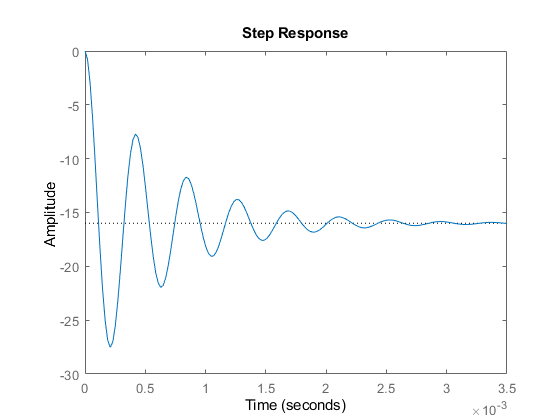


step(24*espaco_de_estado)

**Construindo a função de trasferência a partir da equação conhecida:**

    Construimos então a função de trasferência a partir da equação $G\left(s\right)\;=\;C*{\left(s*I-A\right)}^{-1} *\left(B+D\right)$ e vemos que ela bate com o step aplicado diretamente na SS do item anterior, garantinod que esta é equivalente.

%BLOCO ONDE USO O MODELO DE CONVERSAO CLASSICO (Vo/Vin)


Gs = Cmed*(inv(s * I - Amed_num))*(Bmed_num + Dmat);
Gs = simplify(Gs)

$$Gs = -\frac{150000000}{s^{2}+3125\,s+225000000}$$


[num, den] = numden(Gs);
num = sym2poly(num);
den = sym2poly(den);

Gstf = tf(num,den)

Gstf =
 
         -1.5e08
  ----------------------
  s^2 + 3125 s + 2.25e08
 
Continuous-time transfer function.




A = 24

A = 24

%PLOTANDO A FIGURA PARA ENTRADA DE 24V (1*24)
step(Gstf*A)

ganho = dcgain(Gstf)

ganho = -0.6667


%RESPOSTA IGUAL A ANTERIOR DO SS, OK

**Obtenção de informações do sistema com o matlab:**

    As características do sistema podem ser determinadas a partir de cáclculos com as componentes da função de transferência ou análise visual do gráfico, aqui optamos por funções que retornam mais precisamente o resultado destas análises, como o stepinfo, com a entrada de 24V referente, que pode ser aplicado tanto no espaço de estado quando na função de trasnferência.

info = stepinfo(Gstf*24)

info = struct with fields:
        RiseTime: 7.5398e-05
    SettlingTime: 0.0024
     SettlingMin: -27.5121
     SettlingMax: -7.7194
       Overshoot: 71.9508
      Undershoot: 0
            Peak: 27.5121
        PeakTime: 2.0944e-04


    Vemos aqui a necessidade de controlar o modelo pois ele, em malha aberta, não atinge as especificações de projeto.

    Este modelo que leva  em consideração Vo/Vi é útil para avaliar o comportamento do sistema, porém, quando queremos controla-lo, devemos levar em consideração o Duty Cicle como variável de controle, que é o atuador PWM controlável para ajuste da saída, e não a tensão de entrada que não pode ser facilemnte manipulada.

**Para implementações de funções de trasnferências baseadas no Duty cicle como entrada: EXPLICAR MELHOR DE ONDE VEM**

    Já que para controlar o circuito, precisamos da função de trasnferência em função da variável controlada, o Duty Cicle do MOSFET que caracteriza o PWM do circuito, fazemos a linearização do modelo ao redor do Duty Cicle para obter Vo/D como tf, utilizando a modelagem padrão do modelo de conversor Buck Bosster, $G\left(s\right)\;=\;C*{\left(s*I-A\right)}^{-1} *B_d$, sedo $B_d =\left(A_{\textrm{on}} -A_{\textrm{off}} \right)*X_{\textrm{med}} +\left(B_{\textrm{on}} {-B}_{\textrm{off}} \right)*U_{\textrm{med}}$ e $X_{\textrm{med}}$ a linearização das variáveis de estado em torno do modelo de pequeno sinal do circuito definida por $X_{\textrm{med}} ={\left(-A_{\textrm{med}} \right)}^{-1} *B_{\textrm{med}} *V_{\textrm{in}}$.

    Assim consideramos que a nossa variável de controle será equivalente a pequenas variações em torno do ponto de operação do Duty Cicle "$d\left(t\right)$" para que consigamos nos manter na área linear do ganho em função da razão cíclica aplicaremos:


Xmed = inv(-Amed)*Bmed*Vin;
Bd = (Aon-Aoff)*Xmed + (Bon-Boff)*Vin;

Assim fazemos a função de trasnferência de pequnas variações de X(s) / pequenas variações de D(s) como a seguinte equação desenvolvida a partir do modelo de pequeno sinal, logo em seguida escolhendo a componente de X(s) (Variavel de estado), que queremos a função de tranferência

%MÉTODO DO VIDEO PARA MODELAGEM (Vo/D) https://www.youtube.com/watch?v=LmCLcii8Pqk&ab_channel=Prof.Danillo
Gxds = inv(s*I-Amed) * Bd;

%A PRIMEIRA LINHA É deltaV0(s)/deltaD(s) e a segunda deltaIL(s)/deltaD(s)
Gxds = simplify(Gxds(1))

$$Gxds = \frac{\mathrm{Vin}\,\left(R+{\text{D}}^{2}\,R-2\,\text{D}\,R-\text{D}\,L\,s\right)}{{\left(\text{D}-1\right)}^{2}\,\left(R\,{\text{D}}^{2}-2\,R\,\text{D}+C\,L\,R\,s^{2}+L\,s+R\right)}$$

     Aplicando o ponto de operação fornecido podemos:


Gxds = subs(Gxds,[R, L, C, D, Vin], [4, 20e-6 , 80e-6 , 0.4 , 24]);
Gs = simplify(Gxds);
[num, den] = numden(Gs);
num = sym2poly(num);
den = sym2poly(den);
Gtfbuckb = tf(num,den)

Gtfbuckb =
 
     -250000 s + 4.5e10
  ------------------------
  3 s^2 + 9375 s + 6.75e08
 
Continuous-time transfer function.



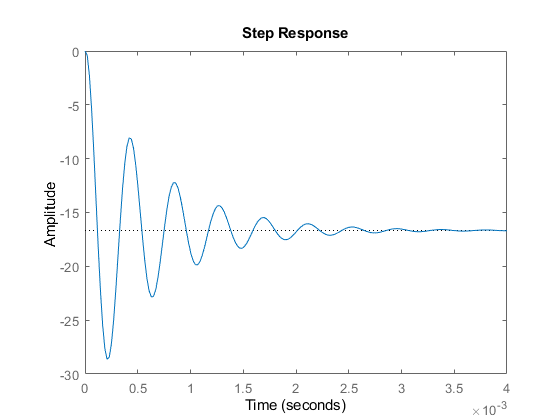


step(Gtfbuckb*(-1/4))


%A PARTIR DAQUI EU N SEI MAIS DE NADA-----------------------------------------
%p = pole(Gtfbuckb);
%z = zero(Gtfbuckb);

%K_controler = 0.000001;
%z_controler = real(p(1))

%PIC = K_controler*(s + abs(z_controler)/s);
%[num, den] = numden(PIC);
%num = sym2poly(num);
%den = sym2poly(den);
%PIC = tf(num,den)

%GsMaPi = PIC*Gtfbuckb

%rlocus(GsMaPi)

%GsMF = feedback(Gtfbuckb*PIC,1)
%step(GsMF)


%rltool(funcao)
%step ((-1/4)*Gtfbuckb)
%syslin = stepinfo((1/4)*Gtfbuckb)



%INFORMAÇÕES DO SISTEMA---------------------------------------------------------
%[y, t] = step(Gstf*24);
%ymax = max(y);
%yest = y(end)
%OS = ((ymax - yest) / yest) * 100
%ganho = dcgain(Gstf);





%SAÍDA ESPERADA:
%V0esperado = (-D/(1-D)) * Vin
%subs(V0esperado,[D,Vin],[0.4,24])


%ANÁLISE DO GANHO
%step (Gstf)

%COERENTE COM O GANHO ESPERADO V0/Vi = 24/16
%subs (Vin , 24);
%saida = Vin * ganho;
%subs (saida,Vin,24)


%----------------------------------------- ESQUEÇA TODO O RESTO A PARTIR DAQUI APENAS DELIRIOS ------------------------------------------------








%SAÍDA ESPERADA:
%V0esperado = (-D/(1-D)) * Vin
%subs(V0esperado,[D,Vin],[0.4,24])



%----------------------------------------------------------------------------------------------------------
%FEEDBACK E TENTATIVA DE CONTROLE PI:
%Ki = 0.01
%num = [0 1]
%den = [1 0]
%integrador = tf(num, den)
%Kp = 2
%Cnormal = 1 + (1/Kp/Ki)
%Gtfbuckb = feedback(PI * Gtfbuckb)
%rlocusx(Gtfbuckb*integrador)









%----------------------------------------------------------------------------------------------------------
%Bd = (Aon-Aoff)*

%Gsbuckb = C*(sI-A)^-1 *Bd

%Amed = [0 ((D-1)/L) ; ((1-D)/C) (-1/(R*C))];
%Bmed = [(D/L) ; 0];
%Cmed = [1 0];
%Dmed = 0;
%I = [1 0; 0 1];

%Vin é o valor médio da tensão de entrada no conversor CC-CC
%Xmed = inv(-Amed) * Bmed * Vin;
%Amed = (Aon*D) + Aoff*(1-D);


%Gssymb = Cmat* inv((s*I)-Amat) * (Bmat+Dmat)
%Gs = subs(Gssymb,[R, L, C, D], [4,20e-6,80e-6,0.4])
%Gs = simplify(Gs)

%[num den] = numden(Gs)
%num = sym2poly(num)
%den = sym2poly(den)

%Gstf = tf(num,den)

%step (Gstf)



%D = 0.4;
%Vi = 24;
%L = 20e-6;
%C = 80e-6;
%R = 4;
%s = tf('s');


%syms IL(t) Vo(t) Vi D L C R s
%s = tf('s')
%Gs =  (-((D*Vi)/C*R*((1-D)^2))  *  (s-((R*(1-D)^2)/D*L))/(s^2+(1/(R*C)*s)+(((1-D)^2)/(C*L))))

%rlocusx(Gs)


**TF Construida a mão a partir do vídeo mencionado(Vo/D):**

syms Dmed
Gsmanual = ((Dmed*Vin)/(C*R*(1-Dmed)^2)) * (s-(((R*(1-Dmed)^2)/(Dmed*L))))/(s^2+(1/(C*R))*s + (((1-Dmed)^2)/(C*L)))

$$Gsmanual = \frac{\mathrm{Dmed}\,\mathrm{Vin}\,\left(s-\frac{R\,{\left(\mathrm{Dmed}-1\right)}^{2}}{\mathrm{Dmed}\,L}\right)}{C\,R\,{\left(\mathrm{Dmed}-1\right)}^{2}\,\left(s^{2}+\frac{s}{C\,R}+\frac{{\left(\mathrm{Dmed}-1\right)}^{2}}{C\,L}\right)}$$

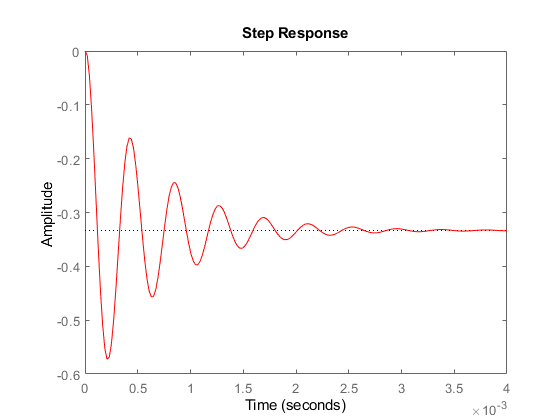

Gsmanual = subs(Gsmanual,[R, L, C, Dmed, Vin], [4,20e-6,80e-6,0.4,24]);
[num, den] = numden(Gsmanual);
num = sym2poly(num);
den = sym2poly(den);
Gsmanual = tf(num,den);
step (Gsmanual*0.005, "r")


%O MÉTODO DA SELECAO DA LINHA É IGUAL ESSE, CONFIRMA QUE É SÓ O LA DE CIMA ESCRITO DIFERENTE